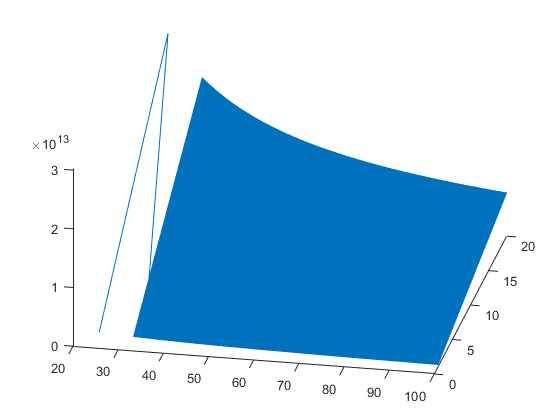

% Parameter
d_piezo=3000e-12;
Vin=50e-3;
Y=250e9; 
area=1.5e3*3e3;

i=1;
j=1;
for t_pmnpt=25:10:100
    e_piezo=d_piezo*(Vin/(t_pmnpt*1e-9));
    i=i+1;
    stress=Y*e_piezo;
    for t_fega=1:0.3:20
        energy(j)=(3/2)*150e-6*area*t_fega*stress;
        t_piezo(j)=t_pmnpt;
        t_magneto(j)=t_fega;
        j=j+1;
        
    end
    i=i+1;
end
%mesh(t_piezo,t_magneto,energy)
plot3(t_piezo,t_magneto,energy)